### **Test problem validation from the book**

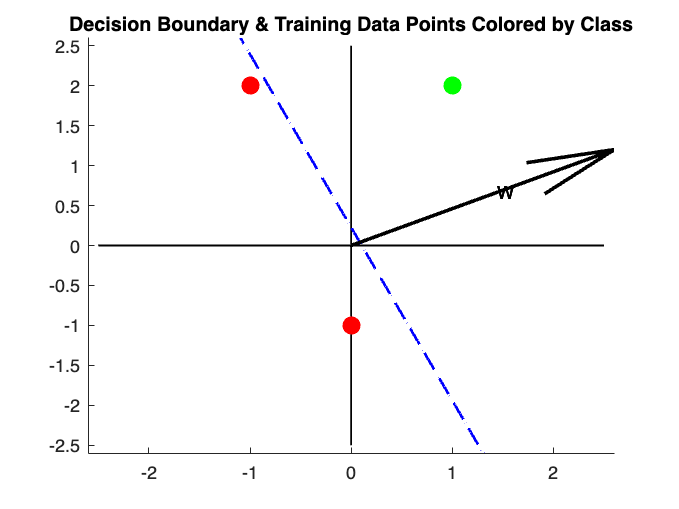

Training completed successfully in 2 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('validation/input_p.txt');
target_data = readmatrix('validation/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 1; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
validation_perceptron = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [validation_perceptron, stop_code] = validation_perceptron.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = 'validation/w.txt';
b_file = 'validation/b.txt';

% Write weights & bias to file
writematrix(validation_perceptron.Weights, w_file, 'Delimiter', 'tab');
writematrix(validation_perceptron.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(validation_perceptron.Weights);

    2.8909    1.3342



disp('Bias:');

Bias:


disp(validation_perceptron.Bias);

   -0.3013




% Validate results
validation_perceptron.classify(input_data(1,:)') % 1

ans = 1

validation_perceptron.classify(input_data(2,:)') % 0

ans = 0

validation_perceptron.classify(input_data(3,:)') % 0

ans = 0

### Example 1 classification 2 classes

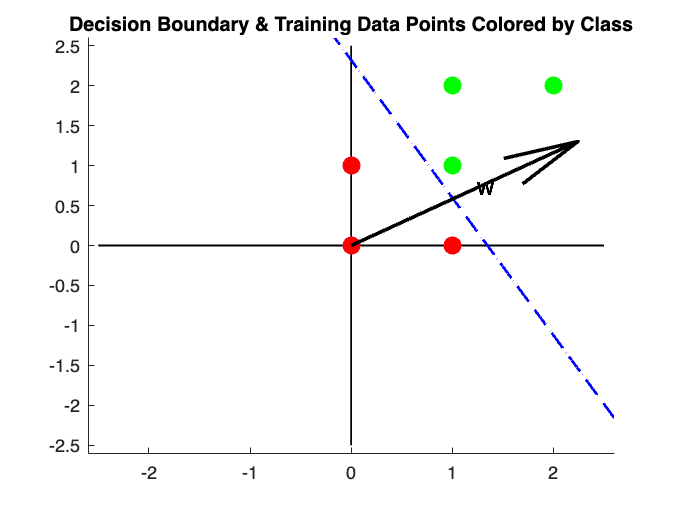

Training completed successfully in 7 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('1/input_p.txt');
target_data = readmatrix('1/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 1; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
perceptron1 = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [perceptron1, stop_code] = perceptron1.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '1/w.txt';
b_file = '1/b.txt';

% Write weights & bias to file
writematrix(perceptron1.Weights, w_file, 'Delimiter', 'tab');
writematrix(perceptron1.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(perceptron1.Weights);

    2.4898    1.4456



disp('Bias:');

Bias:


disp(perceptron1.Bias);

   -3.3537




% Validate results
perceptron1.classify(input_data(1,:)') % 1

ans = 1

perceptron1.classify(input_data(2,:)') % 1

ans = 1

perceptron1.classify(input_data(3,:)') % 1

ans = 1

perceptron1.classify(input_data(4,:)') % 0

ans = 0

perceptron1.classify(input_data(5,:)') % 0

ans = 0

perceptron1.classify(input_data(6,:)') % 0

ans = 0

### Example 2 classification 2 classes

From book P4.1

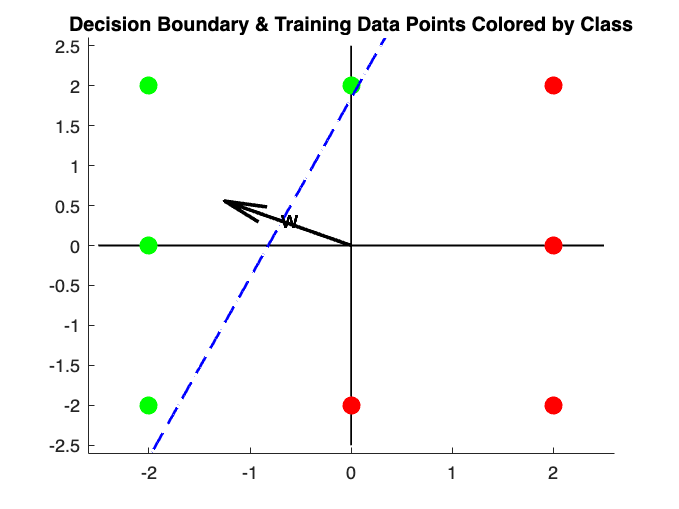

Training completed successfully in 1 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('2/input_p.txt');
target_data = readmatrix('2/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 1; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
perceptron2 = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [perceptron2, stop_code] = perceptron2.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '2/w.txt';
b_file = '2/b.txt';

% Write weights & bias to file
writematrix(perceptron2.Weights, w_file, 'Delimiter', 'tab');
writematrix(perceptron2.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(perceptron2.Weights);

   -1.3901    0.6177



disp('Bias:');

Bias:


disp(perceptron2.Bias);

   -1.1406




% Validate results
perceptron2.classify(input_data(1,:)') % 1

ans = 1

perceptron2.classify(input_data(2,:)') % 0

ans = 0

perceptron2.classify(input_data(3,:)') % 0

ans = 0

perceptron2.classify(input_data(4,:)') % 0

ans = 0

perceptron2.classify(input_data(5,:)') % 0

ans = 0

perceptron2.classify(input_data(6,:)') % 1

ans = 1

perceptron2.classify(input_data(7,:)') % 1

ans = 1

perceptron2.classify(input_data(8,:)') % 1

ans = 1

### Example 3 classification 2 classes

From book P4.4

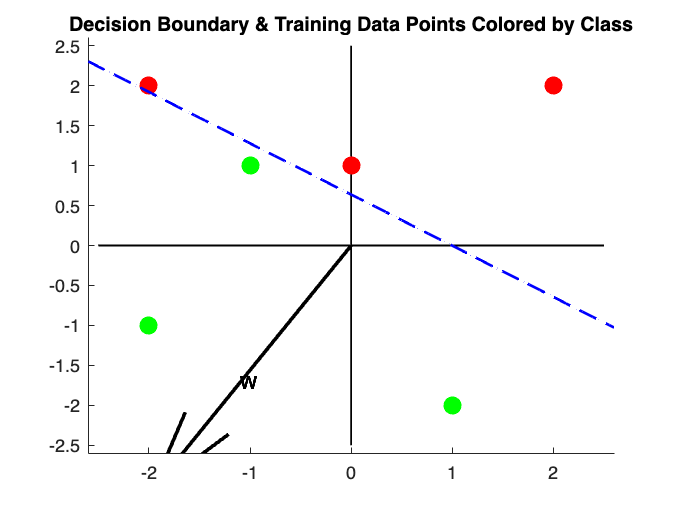

Training completed successfully in 6 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('3/input_p.txt');
target_data = readmatrix('3/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 1; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
perceptron3 = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [perceptron3, stop_code] = perceptron3.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '3/w.txt';
b_file = '3/b.txt';

% Write weights & bias to file
writematrix(perceptron3.Weights, w_file, 'Delimiter', 'tab');
writematrix(perceptron3.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(perceptron3.Weights);

   -2.1945   -3.4233



disp('Bias:');

Bias:


disp(perceptron3.Bias);

    2.1829




% Validate results
perceptron3.classify(input_data(1,:)') % 0

ans = 0

perceptron3.classify(input_data(2,:)') % 1

ans = 1

perceptron3.classify(input_data(3,:)') % 0

ans = 0

perceptron3.classify(input_data(4,:)') % 1

ans = 1

perceptron3.classify(input_data(5,:)') % 0

ans = 0

perceptron3.classify(input_data(6,:)') % 1

ans = 1

### Example 4 classification 4 classes

From book P4.5

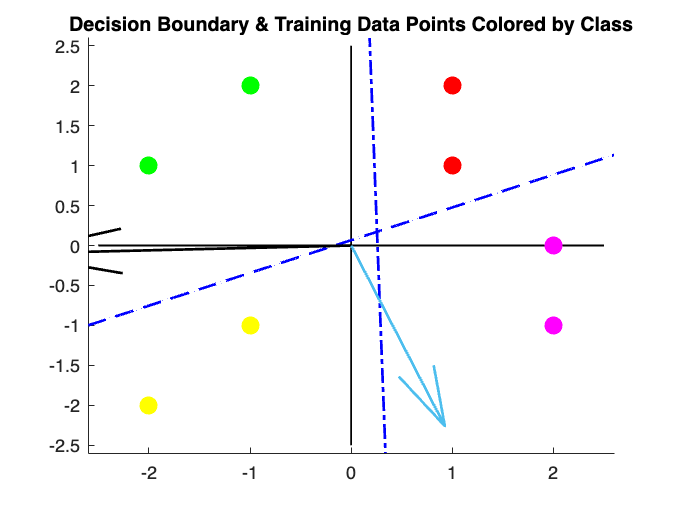

Training completed successfully in 2 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('4/input_p.txt');
target_data = readmatrix('4/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 2; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
perceptron4 = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [perceptron4, stop_code] = perceptron4.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '4/w.txt';
b_file = '4/b.txt';

% Write weights & bias to file
writematrix(perceptron4.Weights, w_file, 'Delimiter', 'tab');
writematrix(perceptron4.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(perceptron4.Weights);

   -3.7601    1.0287
   -0.1135   -2.5101



disp('Bias:');

Bias:


disp(perceptron4.Bias);

    0.1679
    0.9787




% Validate results
perceptron4.classify(input_data(1,:)') % 0,0

ans =      0
     0


perceptron4.classify(input_data(2,:)') % 0,0

ans =      0
     0


perceptron4.classify(input_data(3,:)') % 0,1

ans =      0
     1


perceptron4.classify(input_data(4,:)') % 0,1

ans =      0
     1


perceptron4.classify(input_data(5,:)') % 1,0

ans =      1
     0


perceptron4.classify(input_data(6,:)') % 1,0

ans =      1
     0


perceptron4.classify(input_data(7,:)') % 1,1

ans =      1
     1


perceptron4.classify(input_data(8,:)') % 1,1

ans =      1
     1


### Example 5 classification 4 classes

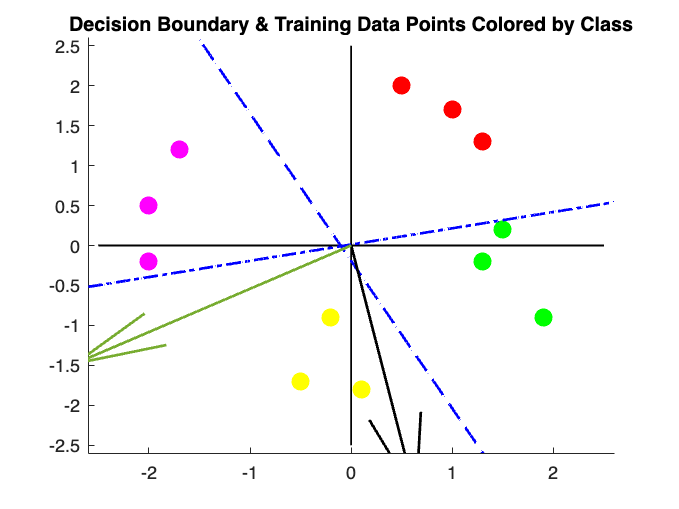

Training completed successfully in 2 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('5/input_p.txt');
target_data = readmatrix('5/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 2; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
perceptron5 = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [perceptron5, stop_code] = perceptron5.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '5/w.txt';
b_file = '5/b.txt';

% Write weights & bias to file
writematrix(perceptron5.Weights, w_file, 'Delimiter', 'tab');
writematrix(perceptron5.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(perceptron5.Weights);

    0.7127   -3.0289
   -3.4995   -1.6404



disp('Bias:');

Bias:


disp(perceptron5.Bias);

   -0.3180
    0.0424




% Validate results
perceptron5.classify(input_data(1,:)') % 0,0

ans =      0
     0


perceptron5.classify(input_data(2,:)') % 0,0

ans =      0
     0


perceptron5.classify(input_data(3,:)') % 0,0

ans =      0
     0


perceptron5.classify(input_data(4,:)') % 1,0

ans =      1
     0


perceptron5.classify(input_data(5,:)') % 1,0

ans =      1
     0


perceptron5.classify(input_data(6,:)') % 1,0

ans =      1
     0


perceptron5.classify(input_data(7,:)') % 0,1

ans =      0
     1


perceptron5.classify(input_data(8,:)') % 0,1

ans =      0
     1


perceptron5.classify(input_data(9,:)') % 0,1

ans =      0
     1


perceptron5.classify(input_data(10,:)') % 1,1

ans =      1
     1


perceptron5.classify(input_data(11,:)') % 1,1

ans =      1
     1


perceptron5.classify(input_data(12,:)') % 1,1

ans =      1
     1


### Example 6 classification 4 classes

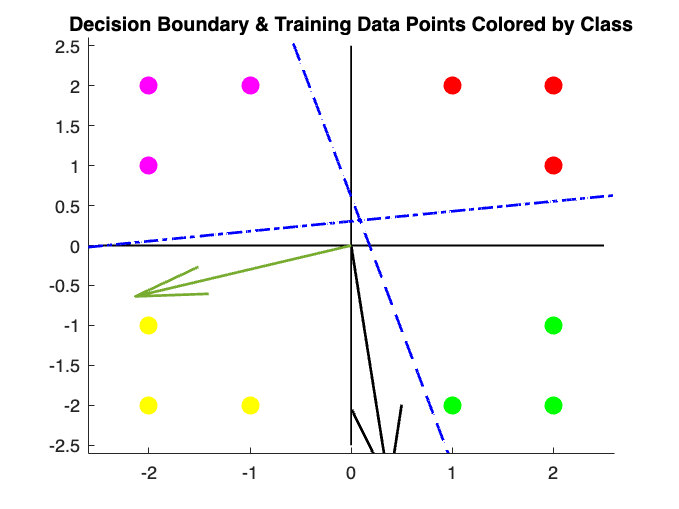

Training completed successfully in 1 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('6/input_p.txt');
target_data = readmatrix('6/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
s = 2; % Number of neurons (2^s to get number of classes)
input_size = size(input_data, 2);
max_epochs = 100; % Maximum number of epochs

% Create and train the perceptron network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
perceptron6 = perceptronNetwork(s, input_size);
while (stop_code ~= 1 && ntry < number_of_retries)
    [perceptron6, stop_code] = perceptron6.train(prototypes, max_epochs);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '6/w.txt';
b_file = '6/b.txt';

% Write weights & bias to file
writematrix(perceptron6.Weights, w_file, 'Delimiter', 'tab');
writematrix(perceptron6.Bias, b_file, 'Delimiter', 'tab');

% Display weights & bias 
disp('Weights:');

Weights:


disp(perceptron6.Weights);

    0.4168   -2.3720
   -3.3431   -0.7080



disp('Bias:');

Bias:


disp(perceptron6.Bias);

    0.4317
    1.0155




% Validate results
perceptron6.classify(input_data(1,:)') % 0,0

ans =      0
     0


perceptron6.classify(input_data(2,:)') % 0,0

ans =      0
     0


perceptron6.classify(input_data(3,:)') % 0,0

ans =      0
     0


perceptron6.classify(input_data(4,:)') % 0,1

ans =      1
     0


perceptron6.classify(input_data(5,:)') % 0,1

ans =      1
     0


perceptron6.classify(input_data(6,:)') % 0,1

ans =      1
     0


perceptron6.classify(input_data(7,:)') % 1,0

ans =      0
     1


perceptron6.classify(input_data(8,:)') % 1,0

ans =      0
     1


perceptron6.classify(input_data(9,:)') % 1,0

ans =      0
     1


perceptron6.classify(input_data(10,:)') % 1,1

ans =      1
     1


perceptron6.classify(input_data(11,:)') % 1,1

ans =      1
     1


perceptron6.classify(input_data(12,:)') % 1,1

ans =      1
     1
